# Lesson II.4:   Euclidean Vector Spaces (F24)

**Affine sets in **${\mathbb R}^n$.    Recall a set of vectors is affine iff every affine combination of vectors in the set is also in the set.   An equivalent definition is that a set is affine iff whenever two vectors are in the set then the line through those two vectors is also in the set.   In ${\mathbb R}^2$, the affine sets are the empty set, the singleton sets (sets with just one point), the lines and the whole plane.   In ${\mathbb R}^3$, the affine sets are the empty set, the singleton sets, the lines, the planes and the whole space.    Because it may not be evident that the empty set and singleton sets fulfill our informal definition of affine set above, we provide more formal definition.

*Definition.*   A set $V\subset{\mathbb R}^n$ is ***affine*** if and only if 

${\bf x}\in V$ and ${\bf y}\in V$ $\Rightarrow\quad \alpha{\bf x}+(1-\alpha){\bf y}\in V$ for all $\alpha\in {\mathbb R}$.

The "line through the two points" is formulated algebraically as the affine combinations of those two points.     For a singleton set, the affine combinations all equal the one point in the set.     The empty set fulfills the definition vacuously (see the follow-up Problem II.4.1).   

The affine sets in ${\mathbb R}^n$ are the solution sets of linear systems of equations.    Moreover, each nonempty affine set in ${\mathbb R}^n$ corresponds to a unique $n\times (n+1)$ reduced row-echelon matrix having no pivot in the last column.   This reduced row-echelon matrix is the augmented matrix for the linear system having the affine set as its solution set.   For the case $n=2$, we list the correspondences explicitly:

**Affine Sets of **${\mathbb R}^2$


$$\matrix{
\left[\matrix{1&0&a\cr 0&1 & b}\right] &\qquad & \left[\matrix{x\cr y}\right]=\left[\matrix{a\cr b}\right]\qquad\qquad\,\,\, &\qquad&\text{singletons} \cr\cr
\left[\matrix{1& a&b\cr 0 & 0 & 0}\right]&\qquad&\left[\matrix{x\cr y}\right]=\left[\matrix{b\cr 0}\right]~+~y\left[\matrix{-a\cr 1}\right]&&\matrix{\text{nonhorizontal}\cr \text{lines}}\cr\cr
\left[\matrix{0&1&a\cr0&0&0}\right]&&\left[\matrix{x\cr y}\right]=\left[\matrix{0\cr a}\right]~+~x\left[\matrix{1\cr 0}\right]&&\matrix{\text{horizontal}\cr \text{lines}}\cr\cr
\left[\matrix{0&0&0\cr 0&0&0}\right]&&\left[\matrix{x\cr y}\right]=x\left[\matrix{1\cr 0}\right]~+~y\left[\matrix{0\cr 1}\right]&&\matrix{\text{whole}\cr \text{plane}}\cr\cr
}$$


Every affine set can be represented ***implicitly ***as the solution set of a linear system or ***explicitly*** in parametric vector form.

In many applications it is common to specify a plane in ${\mathbb R}^3$ in terms of one point in the plane ${\bf x}_0$ and a ***normal*** vector ${\bf n}$ (i.e., a vector that is perpendicular to the plane).   Consider a plane in three dimensions that is the solution set for a system of three linear equations $A{\bf x}={\bf b}$.   Because the plane is a two-parameter family, the system will have two free variables; hence, $\text{rank}(A)=1$.    Thus, in row-echelon form the system of equations has the form

        (II.4.1a)        $\left[\matrix{\alpha & \beta & \gamma\cr 0&0&0 \cr 0&0&0}\right]{\bf x}=\left[\matrix{\delta\cr0\cr0}\right]\qquad\Leftrightarrow\qquad {\bf n}\cdot{\bf x}=\delta\quad\text{where}\quad{\bf n}=\left[\matrix{\alpha\cr\beta\cr\gamma}\right].$

If ${\bf x}_0$ is a point in the plane then ${\bf n}\cdot{\bf x}_0=\delta$; hence, an equation for the plane is

        (II.4.1b)        ${\bf n}\cdot{\bf x}={\bf n}\cdot{\bf x}_0 
\qquad\Rightarrow\qquad
{\bf n}\cdot({\bf x}-{\bf x}_0)=0$.

The last form is sometimes called the ***point-normal form*** of a plane (analogous to the point-slope form of a line in two dimensions).    The point-normal form can be used to represent general hyperplanes in $n$-dimensional space.

We consider the sense in which ${\bf n}$ is normal to the plane:  If ${\bf x}_1$and ${\bf x}_2$ are in the plane then ${\bf n}\cdot {\bf x}_1=\delta$ and ${\bf n}\cdot {\bf x}_2=\delta$.   Taking the difference of these two equations, ${\bf n}\cdot({\bf x}_2-{\bf x}_1)=0$.   That is, ${\bf n}$ is normal (i.e., orthogonal) to the difference of every pair of vectors in the plane.   More generally, if $A$ is a matrix of any dimensions and$A{\bf x}={\bf 0}$, then ${\bf x}$ is orthogonal to each row of $A$.

**Lengths and angles.**   The inner product provides a tool for measuring distances and angles.   Recall,

                    $||\bf x||=\sqrt{ {\bf x}\cdot{\bf x}}$                and                ${\bf x}\cdot{\bf y}=||{\bf x}||\, ||{\bf y}||\,\cos\theta$.

As introduced earlier, there are two important inequalities with clear geometric interpretations, the Cauchy-Schwarz inequality

        (II.4.2a)        $|{\bf x}\cdot{\bf y}|~\le~||{\bf x}||\, || {\bf y}||$

and the triangle inequality

        (II.4.2b)        $||{\bf x}+{\bf y}||\le||{\bf x}||+||{\bf y}||$.

**Proof of the Cauchy-Schwarz inequality.    **The Cauchy-Schwarz inequality (II.4.2b) was proven in Lesson I.1.   Here the proof is repeated in a somewhat different format and fpr a slightly more nuanced version of the inequality.   Specifically, we show that the inequality is strict unless one of the two vectors, ${\bf x}$ and ${\bf y}$, is a multiple of the other.   

To begin, note that if $||{\bf x}||=0$ or $||{\bf y}||=0$, then (II.4.2b) follows immediately as an equality.   Suppose  $||{\bf x}||\ne0$ and $||{\bf y}||\ne0$, and consider ${\bf z}$, the orthogonal projection of ${\bf x}$ onto the line consisting of the multiples of ${\bf y}$.  Though this proof is motivated by the geometry shown in the diagram below, the argument provided is wholly algebraic.

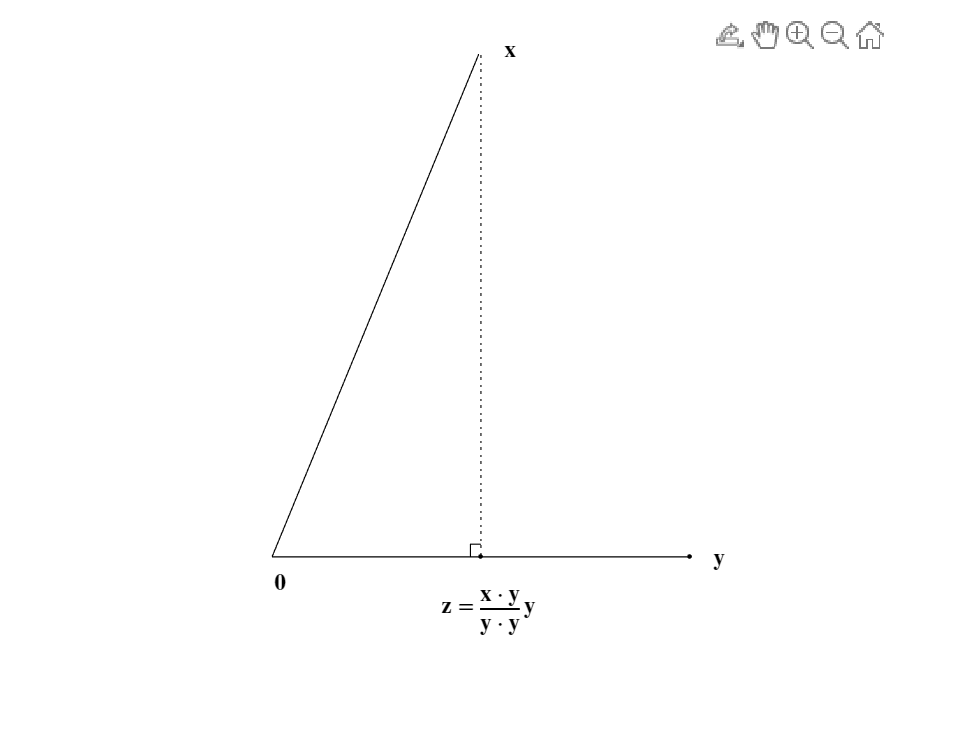

figII4a()

Define ${\bf z}$, a multiple of ${\bf y}$, algebraically as ${\bf z}=({\bf x}\cdot{\bf y}/{\bf y}\cdot{\bf y})\,{\bf y}$.  Geometrically, ${\bf z}$ is the orthogonal projection of ${\bf x}$ onto the line consisting of all multiples of ${\bf y}$; hence,  we expect $||{\bf z}||^2+||{\bf x}-{\bf z}||^2=||{\bf x}||^2$.    This is easily confirmed algebraically:

        
$$\matrix{
\text{(II.4.3a)}\qquad\qquad&
||{\bf z}||^2~+~||{\bf x}-{\bf z}||^2 &=& ||{\bf z}||^2+||{\bf x}||^2-2{\bf x}\cdot{\bf z}+||{\bf z}||^2\qquad\quad \cr
\text{(II.4.3b)}\qquad\qquad&&=& ||{\bf x}||^2+2||{\bf z}||^2-2{\bf x}\cdot{\bf z}\qquad\qquad\qquad \cr
\text{(II.4.3c)}\qquad\qquad&&=& ||{\bf x}||^2+2\left(\frac{{\bf x}\cdot{\bf y}}{{\bf y}\cdot{\bf y}}\right)^2 {\bf y}\cdot{\bf y}-2\frac{{\bf x}\cdot{\bf y}}{{\bf y}\cdot{\bf y}}{\bf x}\cdot{\bf y}\cr
\text{(II.4.3d)}\qquad\qquad&&=& ||{\bf x}||^2\qquad\qquad\qquad\qquad\qquad\qquad
}$$


Hence, from the nonnegativity of $||{\bf x}-{\bf z}||^2$

        (II.4.4)                    $||{\bf x}||^2-||{\bf z}||^2=||{\bf x}-{\bf z}||^2\ge0$.

Moreover, if ${\bf x}$ is not a multiple of ${\bf y}$ then ${\bf x}\ne{\bf z}$ implying the strict inequality $||{\bf x}-{\bf z}||>0$.   Rewriting (II.4.4) with ${\bf z}$ replaced by its definition (${\bf z}=({\bf x}\cdot{\bf y}/{\bf y}\cdot{\bf y})\,{\bf y}$),

        
$$\matrix{
\text{(II.4.5a)}&\qquad&&\qquad&||{\bf x}||^2-\left|\left|\frac{{\bf x}\cdot{\bf y}}{{\bf y}\cdot{\bf y}}{\bf y}\right|\right|^2\ge0 \cr
\text{(II.4.5b)}&\qquad&\Rightarrow&\qquad&||{\bf x}||^2-\left(\frac{{\bf x}\cdot{\bf y}}{{\bf y}\cdot{\bf y}}\right)^2\left|\left|{\bf y}\right|\right|^2\ge0 \cr
\text{(II.4.5b)}&\qquad&\Rightarrow&\qquad&||{\bf x}||^2||{\bf y}||^2-({\bf x}\cdot{\bf y})^2\ge0 \cr
}$$


From which (II.4.2a) follows immediately.   Moreover, unless one of ${\bf x}$ or ${\bf y}$ is a multiple of the other the inequality is strict.

**Polarization identities.   **As noted above, lengths may always be expressed in terms of inner products.   Interestingly, in ${\mathbb R}^n$ the opposite is true as well:

        (II.4.6)        ${\bf x}\cdot{\bf y}=\frac{||{\bf x}+{\bf y}||^2-||{\bf x}-{\bf y}||^2}{4}$

Such an equation relating the dot product and the norm is called a ***polarization identity.  ***The demonstration is another typical calculation:

        
$$\matrix{
\frac{||{\bf x}+{\bf y}||^2-||{\bf x}-{\bf y}||^2}{4} &=&
\frac{({\bf x}+{\bf y})\cdot({\bf x}+{\bf y})-({\bf x}-{\bf y})\cdot({\bf x}-{\bf y})}{4} \qquad\qquad\qquad\cr
 &=&\frac{ \big({\bf x}\cdot{\bf x}+2{\bf x}\cdot{\bf y}+{\bf y}\cdot{\bf y}\big)~-~ \big({\bf x}\cdot{\bf x}-2{\bf x}\cdot{\bf y}+{\bf y}\cdot{\bf y}\big)}{4}\cr
&=&{\bf x}\cdot{\bf y}\qquad\qquad\qquad\qquad\qquad\qquad\qquad\qquad\qquad
}$$


**Relative geometry within a set of vectors.  **For a collection of real vectors ${\bf a}_1,{\bf a}_2,\dots,{\bf a}_n$, a convenient way to compute and arrange the inner products among these vectors is to make a matrix having these vectors as columns $A=\left[\matrix{{\bf a}_1&{\bf a}_2&\cdots&{\bf a}_n}\right]$and to form the Gram matrix:

        (II.4.7)        $G~=~A^TA=\left[\matrix{ 
{\bf a}_1\cdot{\bf a}_1 & {\bf a}_1\cdot{\bf a}_2&\cdots & {\bf a}_1\cdot{\bf a}_n\cr
{\bf a}_2\cdot{\bf a}_1 & {\bf a}_2\cdot{\bf a}_2&\cdots & {\bf a}_2\cdot{\bf a}_n\cr
\vdots &\vdots &\ddots &\vdots\cr
{\bf a}_n\cdot{\bf a}_1 &{\bf a}_n\cdot{\bf a}_2 &\cdots &{\bf a}_n\cdot{\bf a}_n \cr
}\right]$

The Gram matrix contains all the geometric information regarding the relative positions of the vectors.    For example, should we want the distance from ${\bf a}_i$ to ${\bf a}_j$ we have

                    $||{\bf a}_i-{\bf a}_j||=\sqrt{{\bf a}_i\cdot{\bf a}_i-2{\bf a}_i\cdot{\bf a}_j+{\bf a}_j\cdot{\bf a}_j}=\sqrt{G_{ii}-2G_{ij}+G_{jj}}$.

Algebraically, it is easy to see that for a square matrix the determinant of the Gram matrix is the square of the determinant of the underlying matrix:

        (II.4.8)        $|G|=|A^TA|=|A^T|\,|A|=|A|^2$

since $|A^T|=|A|$.    Hence, the magnitude of $|A|$ can be determined from $G$ but not its sign.   Geometrically, the magnitude of the determinant is the $n$-measure of the $n$- dimensional parallelepiped $\cal P$ formed by taking all the linear combinations of the columns $\{{\bf a}_1,{\bf a}_2,\dots,{\bf a}_n\}$with real coefficients from 0 to 1:

        (II.4.9)        ${\cal P} ~=~\left\{\alpha_1{\bf a}_1+\alpha_2{\bf a}_2~+~\cdots~+\alpha_n{\bf a}_n\quad:\quad 0\le\alpha_\ell\le1~\text{for}~\ell=1,\dots,n\right\}$.

The $2-$measure is commonly called *area*; the $3$-measure is commonly called *volume*.

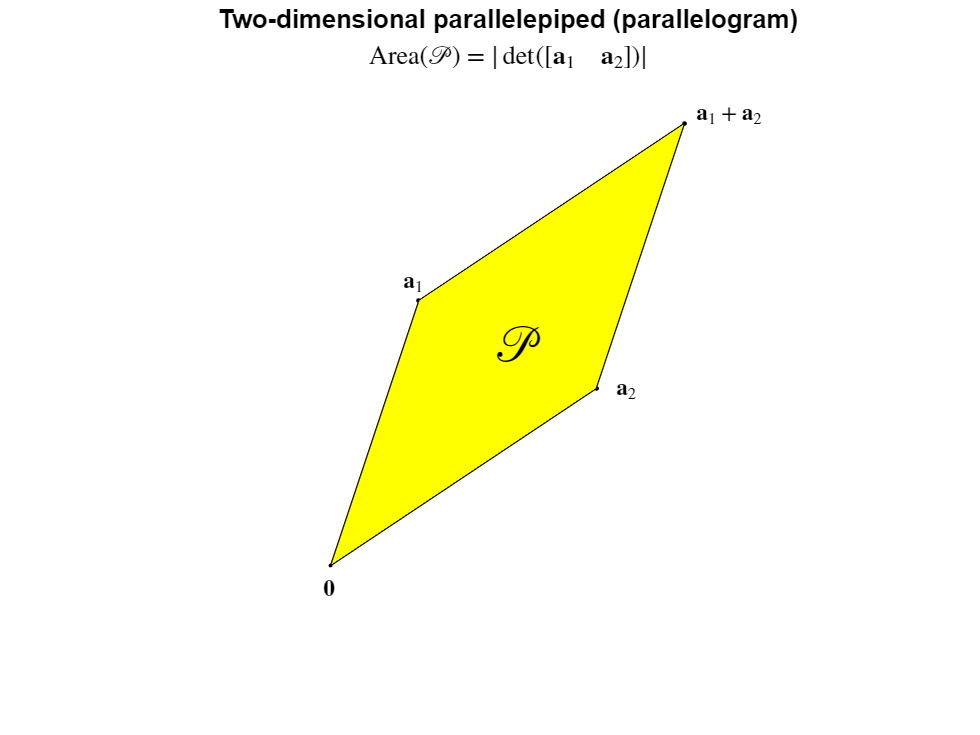

figII4b()

**Isometries.  **Suppose that $U$ is an $n\times n$ orthogonal matrix, and consider the linear map defined through (left) multiplication by $U$:  $T_U({\bf x})=U{\bf x}$.   Let ${\bf x}_1$ and ${\bf x}_2$ be vectors in ${\mathbb R}^n$, and consider their images under $T_U$: ${\bf y}_1=U{\bf x}_1$ and ${\bf y}_2=U{\bf x}_2$.    The key result is that the relative geometric relationship between ${\bf x}_1$ and ${\bf x}_2$ is the same as the relative geometric relationship between ${\bf y}_1$ and ${\bf y}_2$:

        (II.4.10)        $
{\bf y}_i\cdot{\bf y}_j={\bf y}_i^T{\bf y}_j=\big(U{\bf x}_i\big)^T\big({U\bf x}_j\big)={\bf x_i}^T U^T U{\bf x}_j={\bf x}_i^T{\bf x}_j={\bf x}_i\cdot{\bf x}_j$.

The mapping $T_U$ preserves lengths: $||{\bf y}_1||=||{\bf x}_1||$ and $||{\bf y}_2||=||{\bf x}_2||$.  As a length preserving mapping, $T_U$ is known as an ***isometry.  ***

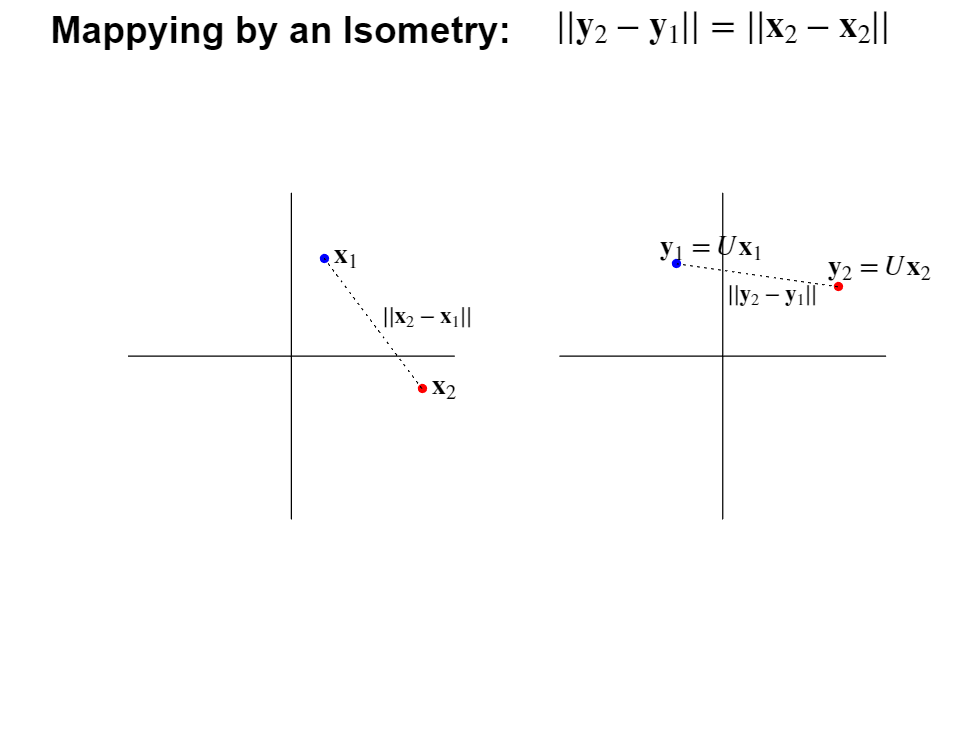

figII4c()

Angles too are preserved: the angle between ${\bf x}_1$ and ${\bf x}_2$ is the same as the angle between ${\bf y}_1$ and ${\bf y}_2$.  Angle preserving maps are said to be ***conformal***.   Moreover, it follows that if $B=UA$ then $A$ and $B$ share the same Gram matrix:

        (II.4.11)        $B^TB=(UA)^T(UA)=A^TU^TUA=A^TA$.

That is, the geometric relationships among the columns of $B$ are the same as those among the columns of $A$.

**The Special Orthogonal Group.**    Since the orthogonal group $\text{O}(n)}$, the set of $n\times n$ orthogonal matrices, is characterized as the set of $n\times n$ real matrices having the $n\times n$ identity matrix as their Gram matrix, the absolute value of the determinant of an orthogonal matrix is 1.   That is, the determinant of an orthogonal matrix must be +1 or -1.   The orthogonal matrices having determinant equal +1 are known as the rotations.  The collection of all the rotation matrices for a given value of $n$ is known as the ***special orthogonal group*** and denoted $\text{SO}(n)}$.  

**Follow-up problems:**

**Problem II.4.1:**   Complete the truth table below for the statement "If $A$ then $B."$


$$
\matrix{
A\backslash B & |&T&|&F&|\cr
\hline T&|& &|& &|\cr
\hline F&|& &|& &|\cr
\hline \,\cr
}$$


Notice that when $A$ is false the conditional statement "If $A$ then $B."$ is always true.    In this situation it is said to be true $vacuously$.   Hence, the empty set is affine because the statement "${\bf x}\in\emptyset$" is never true.

**Problem II.4.2:   **Show that if neither ${\bf x}$ nor ${\bf y}$ is a multiple of the other then the Cauchy-Schwarz inequality (II.4.2a) will be strict.   

**Problem II.4.3:   **For each of the $3\times 4$ reduced row-echelon matrices with no pivot in the last column, find the solution set in parametric vector form and provide a geometric characterization.

            
$$\left[\matrix{1 & 0 & 0 & a\cr 0 & 1 & 0 &b\cr 0 & 0 & 1&c}\right],\quad
\left[\matrix{1 & 0 & a & c\cr 0 & 1 & b &d\cr 0 & 0 & 0&0}\right],\quad
\left[\matrix{1 & a & 0 & b\cr 0 & 0 & 1 &c\cr 0 & 0 & 0&0}\right],\quad
\left[\matrix{0 & 1 & 0 & a\cr 0 & 0 & 1 &b\cr 0 & 0 & 0&0}\right],
$$


            
$$\left[\matrix{1 & a & b & c\cr 0 & 0 & 0 &0\cr 0 & 0 & 0&0}\right],\quad
\left[\matrix{0 & 1 & a & b\cr 0 & 0 & 0 &0\cr 0 & 0 & 0&0}\right],\quad
\left[\matrix{0 & 0 & 1 & a\cr 0 & 0 & 0 &0\cr 0 & 0 & 0&0}\right],\quad
\left[\matrix{0 & 0 & 0 & 0\cr 0 & 0 & 0 &0\cr 0 & 0 & 0&0}\right].
$$


**Problem II.4.4:  **Find a vector normal to the planes in ${\mathbb R}^3$ defined below.    $\text{(a)}\quad \left\{{\bf x}~:~\left [ \matrix{1 & 2 & 3 \cr 6 & 12 & 18} \right]{\bf x}=\left[\matrix{1\cr 0}\right]\right\}\qquad\qquad\text{(b)}\quad 3x+4y+z=1\qquad\qquad\text{(c)}\quad\text{the }~ xy-\text{plane}$

**Problem II.4.5:   **Find two normal vectors (neither a multiple of other) for each of these lines in ${\mathbb R}^3$.

    
$$\text{(a)}\quad \left\{{\bf x}~:~\left [ \matrix{1 & 2 & 3 \cr 4 & 5 & 6 \cr 7&8&9} \right]{\bf x}=\left[\matrix{1\cr 1\cr 1}\right]\right\}\qquad\qquad\text{(b)}\quad {\bf x}=\left[ \matrix{3\cr0\cr2}\right]+y\left[\matrix{ 2\cr1\cr0}\right]\qquad\qquad\text{(c)}\quad\text{the }~ x-\text{axis}$$


**Problem II.4.6:   **Expand $||{\bf x}+{\bf y}||^2$ in terms of inner products and show that the triangle inequality follows immediately from the Cauchy-Schwarz inequality.

**Problem II.4.7:  **Show that the matrices $\left[\matrix{1 &0 \cr 0 & 1}\right]$ and $\left[\matrix{-1 & 0 \cr 0 & 1}\right]$share the same Gram matrix but have different determinants.

**Problem II.4.8:  **What is the volume of the parallelepiped generated by the set of vectors $\left\{\left[\matrix{7\cr1\cr0}\right],~\left[\matrix{1\cr0\cr0}\right],~\left[\matrix{3\cr5\cr1}\right]\right\}$?

**Problem II.4.9: **Consider the three vectors


$${\bf x}_1=\left[\matrix{2\cr 1\cr 1}\right],\qquad\qquad {\bf x}_2=\left[\matrix{1\cr 2\cr 1}\right],\qquad\qquad 
{\bf x}_3=\left[\matrix{1\cr 1\cr 2}\right].$$


    (a)   What is the volume of the parallelepiped generated by these three vectors?

    (b)   Find an equation for the plane through the three points.   Find a normal vector.

    (c)   What are the angles ($\theta_{12},\theta_{13},\theta_{23}$) between each pair of vectors?

    (d)   Find the area of the triangle having these three points as its vertices.

**Problem II.4.10:   **Show that for a given value of $n$ the set of rotation matrices $SO(n)$ is closed under matrix multiplication, matrix inversion, and matrix transpose.    

**Problem II.4.11:   **Suppose that $\theta\in{\mathbb R}$ and ${\bf x}\in {\mathbb R}^2$ is a not the zero vector.   Show each of the following is an orthogonal matrix and compute its determinant.

$\text{(a)}\quad\left[\matrix{\cos\theta & -\sin\theta\cr \sin\theta & \cos\theta}\right]\qquad
\text{(b)}\quad\left[\matrix{\cos2\theta & \sin2\theta \cr \sin2\theta & -\cos2\theta}\right]\qquad
\text{(c)}\quad I-2\frac{{\bf x}{\bf x}^T}{{\bf x}^T{\bf x}}$.

**Problem II.4.12:**   Let $A=\left[\matrix{ a& b \cr c & d }\right]$ and $C=\{{\bf x}\in{\mathbb R}^2~:~ ||{\bf x}||\le1\}$.    What is the area of $H=\{~A{\bf x}\quad :\quad {\bf x}\in C\}$?

**Problem II.4.13:   **Show that $SO(2)$ is commutative; that is, all $2\times 2$ orthogonal matrices commute with each other.

**Problem II.4.14:  **Show that $SO(3)$ is not commutative.

function figII4a()
figure
hold on
axis([-1 3 -0.2 1.1])
axis off
plot([0 1],[0 1],'k')
plot(1,1,'.k')
text(1.1,1,'${\bf x}$','Interpreter','latex')
plot([0 2],[0 0],'k')
plot(2,0,'.k')
text(2.1,0,'${\bf y}$','Interpreter','latex')
plot(1,0,'.k')
text(0.8,-0.1,'${\bf z}=\frac{ {\bf x}\cdot{\bf y} }{ {\bf y}\cdot{\bf y} }{\bf y}$','Interpreter','latex')
text(0,-0.05,'${\bf 0}$','Interpreter','latex')
plot([1 1],[1 0],':k')
plot([0.95 0.95 1],[0 0.025 0.025],'k')
end

function figII4b()
figure
axis([-1 5.5 -1 5.5])
hold on
axis equal
axis off
a1=[1;3];
a2=[3;2];
plot(0,0,'.k','MarkerSize',5)
text(-.1,-.25,'${\bf 0}$','Interpreter','latex')
plot(a1(1),a1(2),'.k')
text(a1(1)-0.2,a1(2)+0.2,'${\bf a}_1$','Interpreter','latex')
plot(a2(1),a2(2),'.k')
text(a2(1)+0.2,a2(2),'${\bf a}_2$','Interpreter','latex')
plot(a1(1)+a2(1),a1(2)+a2(2),'.k')
text(a1(1)+a2(1)+0.1,a1(2)+a2(2)+0.1,'${\bf a}_1+{\bf a}_2$','Interpreter','latex')
plot([0 a1(1) a1(1)+a2(1) a2(1) 0],[0 a1(2) a1(2)+a2(2) a2(2) 0])
fill([0 a1(1) a1(1)+a2(1) a2(1) 0],[0 a1(2) a1(2)+a2(2) a2(2) 0],'y')
text(1.8,2.5,'$\cal P$','Interpreter','latex','FontSize',22)
title('Two-dimensional parallelepiped (parallelogram)')
subtitle('Area($\cal P$) = $|\det([{\bf a}_1\quad{\bf a}_2])|$','Interpreter','latex')
shg
end

function figII4c()
figure
clf
subplot(1,2,1)
title('Mappying by an Isometry:  ','FontSize',16)
axis([-5 5 -2 5])
hold on
axis equal
axis off
plot([-5 5],[0 0],'k')
plot([0 0],[-5 5],'k')
x1=[1;3];
x2=[4;-1];
plot(x1(1),x1(2),'.b','MarkerSize',12)
text(x1(1)+0.2,x1(2)+0.1,'${\bf x}_1$','Interpreter','latex','FontSize',12)
plot(x2(1),x2(2),'.r','MarkerSize',12)
text(x2(1)+0.2,x2(2)+0.1,'${\bf x}_2$','Interpreter','latex','FontSize',12)
plot([x1(1) x2(1)],[x1(2) x2(2)],':k')
text((x1(1)+x2(1))/2+0.2,(x1(2)+x2(2))/2+0.2,'$||{\bf x}_2-{\bf x}_1||$','Interpreter','latex','FontSize',10)
subplot(1,2,2)
axis([-5 5 -2 5])
hold on
axis equal
axis off
plot([-5 5],[0 0],'k')
plot([0 0],[-5 5],'k')
title('$||{\bf y}_2-{\bf y}_1||=||{\bf x}_2-{\bf x}_2||$','Interpreter','latex','FontSize',16)
theta=pi/4;
U=[cos(theta) -sin(theta); sin(theta) cos(theta)];
y1=U*x1;
y2=U*x2;
plot(y1(1),y1(2),'.b','MarkerSize',12)
text(y1(1)-0.6,y1(2)+0.5,'${\bf y}_1=U{\bf x}_1$','Interpreter','latex','FontSize',12)
plot(y2(1),y2(2),'.r','MarkerSize',12)
text(y2(1)-0.4,y2(2)+0.6,'${\bf y}_2=U{\bf x}_2$','Interpreter','latex','FontSize',12)
plot([y1(1) y2(1)],[y1(2) y2(2)],':k')
text((y1(1)+y2(1))/2-01,(y1(2)+y2(2))/2-0.6,'$||{\bf y}_2-{\bf y}_1||$','Interpreter','latex','FontSize',10)
shg
end